# ELABORATO 2 -  CONFRONTO TRA I PRODOTTI MATRICE VETTORE PER RIGHE, COLONNE E BLOCCHI

# LO BRUTTO FABIO / MAIONE PAOLO

## INTRODUZIONE

Si presenta un confronto tra le performance dei tre possibili algoritmi per effettuare il prodotto matrice vettore in parallelo. In particolare vengono di seguito considerati i seguenti tre casi significativi: il caso in cui il numero di righe è maggiore numero di colonne, il caso in cui il numero di righe è minore del numero di colonne ed, infine, il caso in cui la matrice è quadrata. Inoltre, per un equo confronto è stato fissato il numero di processori *p* a 4. 

Si noti che nel caso di distribuzione della matrice a blocchi, avere 4 processori equivale ad una griglia bidimensionale di dimensione 2*2.

Il parametro di performance usato per il confronto è l'efficienza *E(p)*.

Di seguito con *M* si indicherà il numero di righe della matrice, con *N* il numero di colonne.

## CASO MATRICE SBILANCIATA - M > N

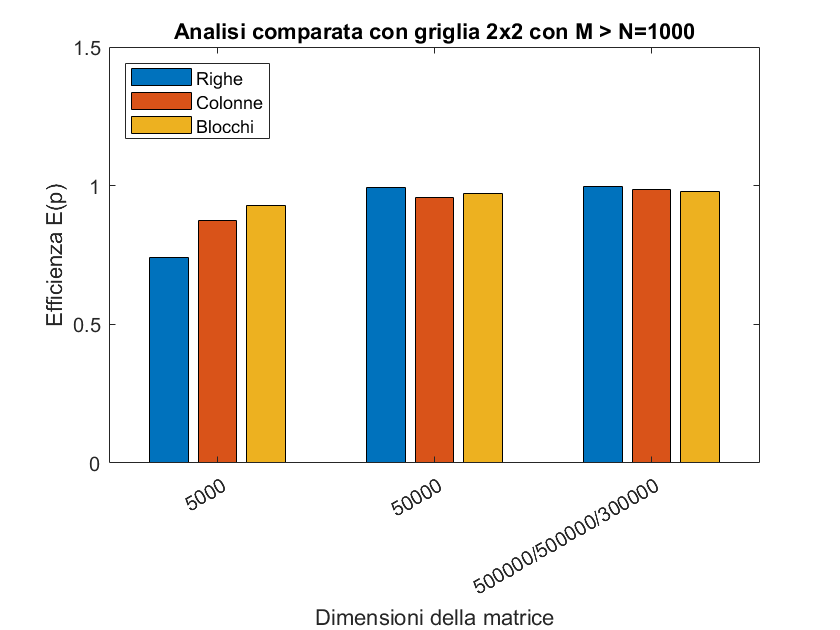

%esecuzione script per matrici sbilanciate (m>n)
m_magg_n

Analizzando il grafico a barre si possono trarre le seguenti conclusioni:

- nel caso di M=5000 la distribuzione migliore risulta essere quella a blocchi;

- nel caso M=50000 oppure M=500000/300000 la distribuzione migliore risulta essere quella a righe;

- la distribuzione per colonne ha delle prestazioni intermedie tra le due ma quasi costante in ogni configurazione.

Pertanto, è ragionevole considerare che la distribuzione è quella per righe quando la matrice è fortemente sbilanciata mentre è quella per blocchi se è poco sbilanciata. 

## CASO MATRICE SBILANCIATA - M < N

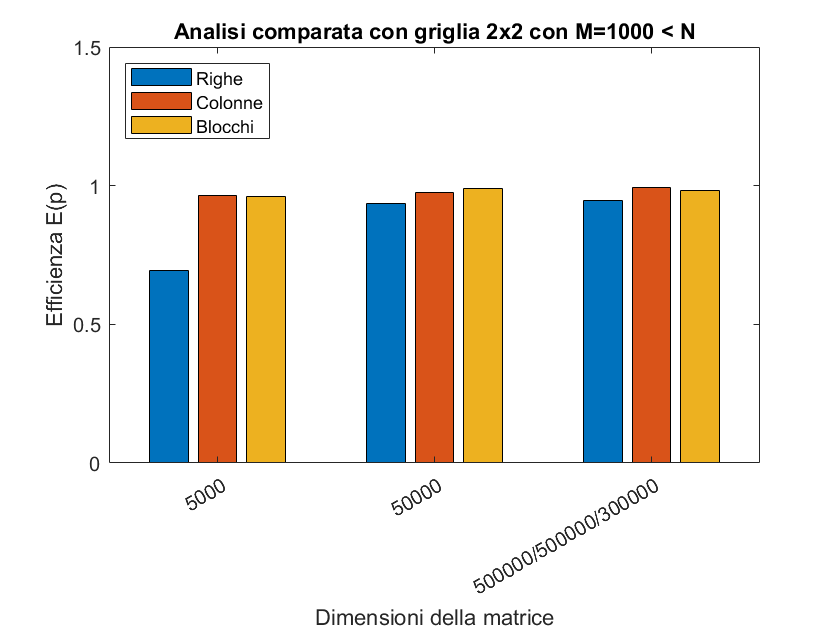

%esecuzione script per matrici bilanciate
m_min_n

Analizzando il grafico a barre si possono trarre le seguenti conclusioni:

- nel caso di N=5000 oppure N=500000/300000 la distribuzione migliore risulta essere quella a colonne;

- nel caso N=50000 la distribuzione per blocchi è quella migliore

E' evidente che la distribuzione per righe non ha prestazioni comparabili alle altre due in ogni configurazione mentre per colonne e blocchi si hanno prestazioni pressochè simili e ciò è ovvio dal momento che, tenendo fisso il numero di righe M, nella distribuzione per blocchi risulta discriminante la dimensione delle colonne via via crescente.

## CASO MATRICE QUADRATA

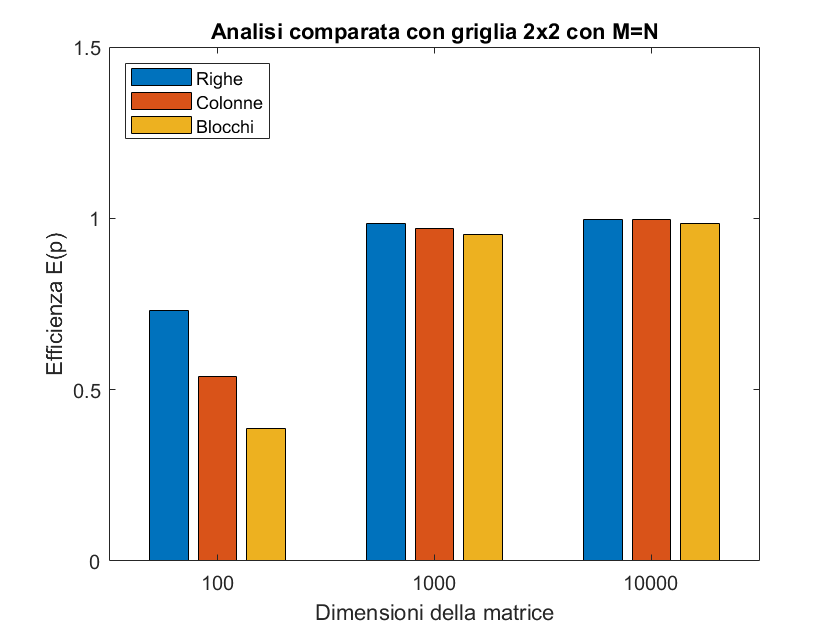

%esecuzione script per matrici sbilanciate (m<n)
m_ugu_n

Analizzando il grafico a barre si possono trarre le seguenti conclusioni:

- nel caso M=N=100 a causa delle dimensioni ridotte della matrice, l'efficienza è peggiore di almeno il 30% rispetto alle altre due configurazioni; tuttavia la distribuzione per righe risulti essere la migliore;

- nel caso M=N=1000, la distribuzione migliore risulta essere quella per righe;

- nel caso M=N=10000, la distribuzione migliore risulta essere quella per righe, seppur di poco.

Si può notare come però, al crescere della dimensione del problema in esame, l'efficienza nel caso di distribuzione a blocchi cresca, fino quasi a raggungere quella nel caso di quella a righe che rimane pressochè costante tra 1000 e 10000. Questo significa che, per matrici quadrate più grandi di quelle prese in esame in questo elaborato, la distribuzione a blocchi sembra essere la soluzione più efficiente.

## Considerazioni conclusive

In conclusione, la distribuzione a righe risulta, in media, particolarmente la più efficiente nel caso in cui la matrice è molto sbilanciata rispetto alle righe (M >> N), mentre, quella a colonne nel caso in cui è molto sbilanciata rispetto alle colonne (N >> M). Infine nei casi in cui la matrice è quadrata o "poco" sbilanciata la distrubuzione a blocchi risulta mediamente la soluzione migliore.

Inoltre c'è da considerare che gli algoritmi sono stati implementati in C. Poiché in C l'allocazione delle matrici avviene per riga, in generale, si è riscontrato un numero di casi maggiore in cui l'efficienza è migliore nella distribuzione per righe, in quanto non occorre basarsi su altre strutture dati o altre funzioni. In MATLAB, per esempio, dove le matrici sono allocate per colonne, si avrebbbero probabilmente risultati opposti.

Chiaramente non esiste il metodo migliore in tutti i casi; ciò infatti significherebbe che quello sarebbe usato in ogni circostanza e, dunque, gli altri due metodi non sarebbero neanche implementati o studiati.